## The Flyaway-kit Problem

% Set up the weight, size and cost values for each type of item
weights = [3 5 2 5 6 2 4 7 5 3];
sizes = [5 4 7 4 6 2 5 7 3 4];
costs = [3 3 3 3 3 3 3 3 3 3];
average_demand = [4 4 4 4 4 4 4 4 4 4]; 
% Weight and size capacities will vary between 0 and a maximum value 
% for each
max_weight = 30;
max_size = 30;

% set up the matrices that will store how many of each item will be chosen to
% cargo for each weight 0:max_weight and size 0:max_size

item_allocations = zeros(max_weight+1,max_size+1,1);
% rows are weights
% columns are sizes
% each matrix shows the allocation of one type of good

% set up the matrices that will store the outcomes for each stage of the
% process, from 1 to length(weights).

cost_outcomes = zeros(max_weight+1, max_size+1, length(weights));

% rows are weights
% columns are sizes
% each matrix 1:length(weights) shows the expected cost of transporting
% as many types of goods as stages

%First Stage Calculation

% Only the first type of item will be used
for weight = 0:max_weight
    for size = 0:max_size
        
        % calculate up to how many of type 1 you can put in the vehicle
        max_alloc = min([fix(weight/weights(1)) fix(size/sizes(1))]);
        
        % calculate the expected cost for each possible allocation 0:max_alloc
        % to obtain the one that's minimum
        min_cost = exp(1000);
        optimal_allocation = 0;
        
        for alloc = 0:max_alloc
            
            % for each allocation, there will be a new expected cost 
            expected_demand = 0;
            for demand = (alloc+1):20

                x = poisspdf(demand,average_demand(1)); % likelihood of having 
                % "demand" many items demanded
                y = demand - alloc; % number of items that are missing
                z = x*y; % averaged effect of y on expected_demand
                expected_demand = expected_demand + z;                
            end

            expected_cost = costs(1)*expected_demand;
            if expected_cost < min_cost
                min_cost = expected_cost;
                optimal_allocation = alloc;
            end
        end
        
        % Now the allocation that creates the minimum averaged cost is
        % known. Attribute it to the right storage with the right weight
        % and size.

        item_allocations(weight+1,size+1) = optimal_allocation;
        cost_outcomes(weight+1,size+1,1) = min_cost;

    end
end

item_allocations(26:31,26:31)

ans =      5     5     5     5     5     6
     5     5     5     5     5     6
     5     5     5     5     5     6
     5     5     5     5     5     6
     5     5     5     5     5     6
     5     5     5     5     5     6


cost_outcomes(26:31,26:31,1)

ans =     1.2309    1.2309    1.2309    1.2309    1.2309    0.5863
    1.2309    1.2309    1.2309    1.2309    1.2309    0.5863
    1.2309    1.2309    1.2309    1.2309    1.2309    0.5863
    1.2309    1.2309    1.2309    1.2309    1.2309    0.5863
    1.2309    1.2309    1.2309    1.2309    1.2309    0.5863
    1.2309    1.2309    1.2309    1.2309    1.2309    0.5863


% Second Stage Calculation
for stage = 2:length(weights)

    % We are going to use the allocations from the previous stage. So store
    % it again, and remake the "item_allocations" array of matrices.
    previous_stage_allocations = item_allocations;
    item_allocations = zeros(max_weight+1,max_size+1,stage);

    for weight = 0:max_weight
        for size = 0:max_size
            % find out how many of type "stage" you can put in
            max_alloc = min([fix(weight/weights(stage)) fix(size/sizes(stage))]);
        
            % calculate average cost for each possible allocation 0:max_alloc
            % to obtain the one that's minimum
            min_cost = exp(1000);
            optimal_allocation = 0;
            
            for alloc = 0:max_alloc
                expected_demand = 0;
                for demand = (alloc+1):20
                    x = poisspdf(demand,average_demand(stage));
                    y = demand - alloc;
                    z = x*y;
                    expected_demand = expected_demand + z; 
                end
                expected_cost = expected_demand*costs(stage);
                
                d = weight+1-alloc*weights(stage);
                e = size+1-alloc*sizes(stage);
                expected_cost = expected_cost + cost_outcomes(d,e,stage-1);
                
                if expected_cost <= min_cost
                    min_cost = expected_cost;
                    optimal_allocation = alloc;
                end
            end 

            % now, the best allocation for type "stage" is stored in
            % optimal_allocation and the cost is stored in min_cost. Place
            % these in the right places
            o = optimal_allocation;
            m = min_cost;
            w = weights(stage);
            s = sizes(stage);

            item_allocations(weight+1,size+1,1:(stage-1)) = previous_stage_allocations(weight+1-(o*w),size+1-(o*s),:);
            item_allocations(weight+1,size+1,stage) = o;
            cost_outcomes(weight+1,size+1,stage) = min_cost;
    
        end
    end
end

for i= 26:31
    fprintf("Optimal Allocation for weight and size capacity = "+num2str(i-1)+":")
    a = squeeze(item_allocations(i,i,:));
    transpose(a)
end

Optimal Allocation for weight and size capacity = 25:

ans =      1     0     0     0     0     3     0     0     2     2


Optimal Allocation for weight and size capacity = 26:

ans =      1     0     0     1     0     5     0     0     1     1


Optimal Allocation for weight and size capacity = 27:

ans =      1     0     0     0     0     4     0     0     2     2


Optimal Allocation for weight and size capacity = 28:

ans =      0     0     0     1     0     4     1     0     1     2


Optimal Allocation for weight and size capacity = 29:

ans =      1     0     0     0     0     5     0     0     2     2


Optimal Allocation for weight and size capacity = 30:

ans =      1     1     0     1     0     3     0     0     1     2



fprintf("The minimum costs for weights and sizes from 25 to 30:")

The minimum costs for weights and sizes from 25 to 30:

cost_outcomes(26:31,26:31,length(weights))

ans =    97.7583   97.5385   97.4507   96.4983   96.0587   96.0587
   97.6705   97.4507   97.3187   96.4983   95.8389   95.8389
   97.5385   96.7181   96.0587   95.8389   95.8389   95.3848
   97.4507   96.7181   96.0587   95.8389   95.4726   95.0330
   96.7181   96.0587   95.8389   95.6046   94.9452   94.7254
   96.7181   96.0587   95.8389   95.4726   94.8132   94.5935


% Obtaining the expected cost for a given allocation 
a = [1 1 0 1 0 3 0 0 1 2];
b = item_allocations(31,31,:);
exp_cost = 0

exp_cost = 0

for i = 1:length(a)
    for demand = (a(i)+1):20
        x = poisspdf(demand,average_demand(i));
        y = costs(i)*(demand - a(i))*x;
        exp_cost = exp_cost + y;
    end
end
fprintf("The optimal expected cost for the current allocation: " + num2str(exp_cost));

The optimal expected cost for the current allocation: 94.5935

p = 0;
for i = 2:100
    p = p + (i-1)*poisspdf(i,4);
end
3*p + 108

ans = 117.0549

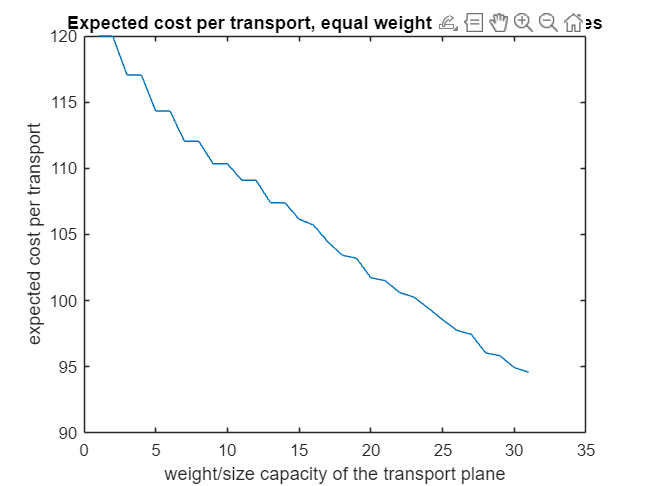

plot(diag(cost_outcomes(:,:,10)))
title("Expected cost per transport, equal weight and size capacities")
xlabel("weight/size capacity of the transport plane")
ylabel("expected cost per transport")

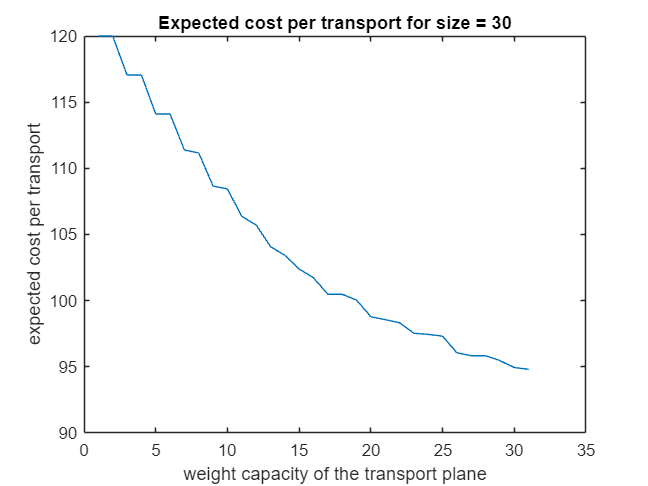



plot(cost_outcomes(:,30,10))
title("Expected cost per transport for size = 30")
xlabel("weight capacity of the transport plane")
ylabel("expected cost per transport")

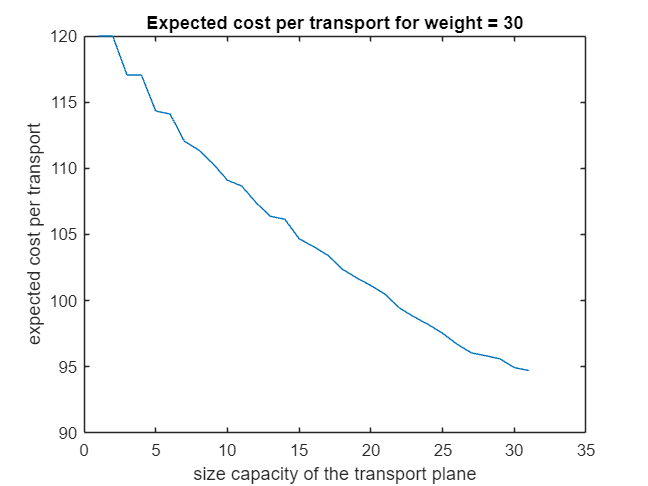


plot(cost_outcomes(30,:,10))
title("Expected cost per transport for weight = 30")
xlabel("size capacity of the transport plane")
ylabel("expected cost per transport")